# Human Activity Recognition: Mobile Sensor Data

This example shows how to train and use a Machine Learning Model, able to classify which activity (Sitting-1, Standing-2, Walking-3, Running-4, and Dancing-5) is the person holding the mobile phone is doing.

The data of accelaration in the 3 directions (X,Y,Z) from the mobile sensors are used as input for this model.

The first part of this example is about training the Machine Learning Model and then this model will be used for the new input data from the phone's sensors.

%cd '';

## TRAINING THE MACHINE LEARNING MODEL

Once the trained our model, we do not need to repeat this step everytime. We can save the model and load it to be ready to use it for our classification. For this option unselect `DoTraining` below.

DoTraining = true ;

%if DoTraining

### Load Sample Data Set

Load the `humanactivity` data set.

load humanactivity

The `humanactivity` data set contains 24,075 observations of five different physical human activities: Sitting, Standing, Walking, Running, and Dancing. Each observation has 60 features extracted from acceleration data measured by smartphone accelerometer sensors. The data set contains the following variables:

- `actid` — Response vector containing the activity IDs in integers: 1, 2, 3, 4, and 5 representing Sitting, Standing, Walking, Running, and Dancing, respectively

- `actnames` — Activity names corresponding to the integer activity IDs

- `feat` — Feature matrix of 60 features for 24,075 observations

- `featlabels` — Labels of the 60 features

The Sensor HAR (human activity recognition) App [[1]](docid:stats_ug.mw_61c32611-104e-4534-8522-c3078723aabd) was used to create the `humanactivity` data set. When measuring the raw acceleration data with this app, a person placed a smartphone in a pocket so that the smartphone was upside down and the screen faced toward the person. The software then calibrated the measured raw data accordingly and extracted the 60 features from the calibrated data. For details about the calibration and feature extraction, see [[2]](docid:stats_ug.mw_8b56f1d0-5b6d-48bb-a6bc-ab2077f3b19c) and [[3]](docid:stats_ug.mw_46da34e0-0e4d-4f90-8e2e-2c98d448b62b), respectively.

### Prepare Data

This Example uses 90% of the observations to train a model that classifies the five types of human activities and 10% of the observations to validate the trained model. 

- *Use *[`cvpartition`](docid:stats_ug.brxwayf-1)* to specify a 10% holdout for the test set. Suggestion: you want to include the *'Holdout' * option.*

rng('default') % For reproducibility
Partition = cvpartition(feat(:,1), "HoldOut", .1, 'Stratify', false)

trainingInds = training(Partition); % Indices for the training set
XTrain = feat(trainingInds,:); %Training Data

Partition = Hold-out cross validation partition
   NumObservations: 24075
       NumTestSets: 1
         TrainSize: 21668
          TestSize: 2407

YTrain = actid(trainingInds); % Training Labels

testInds = test(Partition); % Indices for the test set
XTest = feat(testInds,:);
YTest = actid(testInds);

    2. Convert the feature matrix `XTrain` and the response vector `YTrain` into a table to load the training data set in the Classification Learner app.

tTrain = array2table([XTrain YTrain])

Specify the variable name for each column of the table.

tTrain.Properties.VariableNames = [featlabels' 'Activities'];

### Train Boosted Tree Ensemble Using Classification Learner App

Train a classification model by using the Classification Learner app. 

    3. To open the Classification Learner app, enter `classificationLearner` at the command line. Alternatively, click the **Apps** tab, and click the arrow at the right of the **Apps** section to open the gallery. Then, under **Machine Learning**, click **Classification Learner**.

    4. On the **Classification Learner** tab, in the **File** section, click **New Session** and select **From Workspace**. 

    5. In the New Session dialog box, click the arrow for **Workspace Variable**, and then select the table `tTrain`. Classification Learner detects the predictors and the response from the table.

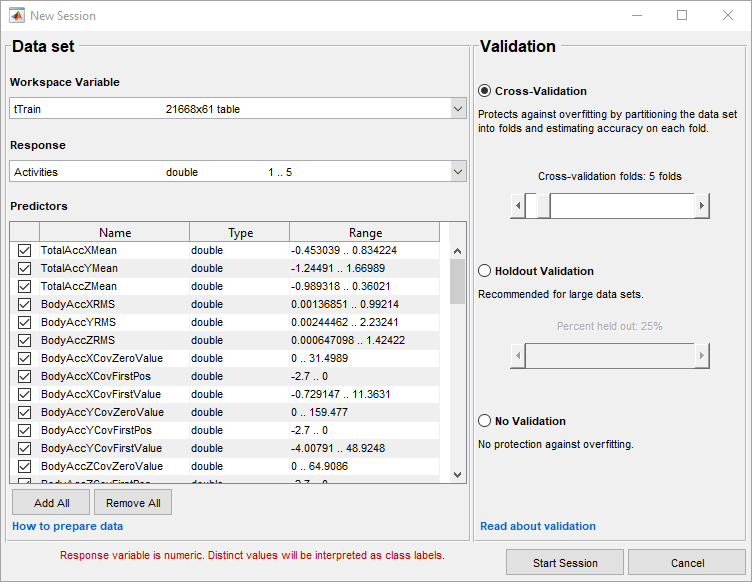

### Train Boosted Tree Ensemble at Command Line

    10. Alternatively, you can train the same classification model at the command line. 

template = templateTree('MaxNumSplits',20);
classificationEnsemble = fitcensemble(XTrain,YTrain, ...
    'Method','AdaBoostM2', ...

tTrain = 21668×61 table
     Var1       Var2        Var3       Var4        Var5        Var6       Var7      Var8      Var9       Var10     Var11     Var12       Var13      Var14      Var15       Var16     Var17     Var18     Var19     Var20     Var21      Var22        Var23        Var24        Var25        Var26        Var27       Var28     Var29     Var30     Var31     Var32     Var33       Var34        Var35<

    'NumLearningCycles',30, ...
    'Learners',template, ...
    'LearnRate',0.1, ...
    'ClassNames',[1; 2; 3; 4; 5]);

partitionedModel = crossval(classificationEnsemble,'KFold',5);
validationAccuracy = 1-kfoldLoss(partitionedModel)

testAccuracy = 1-loss(classificationEnsemble,XTest,YTest)

saveLearnerForCoder(classificationEnsemble,'EnsembleModel.mat');
mdl=classificationEnsemble;

% else
%     load EnsembleModel.mat
%     mdl = loadLearnerForCoder('EnsembleModel.mat'); 
% end

## Classification of activity using mobile sensor data

    11. From MATLAB Mobile App, go to Sensors and activate the accelerometers and start logging.

When you stop logging, in your ThingSpeak there will be a new timetable variable with acceleration data collected during the interval of time of logging.

### Load the data from your sensor


chID = 998255

%for i = 1:height(acceleration)
  %   reponse = thingSpeakWrite(chID,acceleration(i,:), 'WriteKey', 'KF1LCOXFRLPO2HAK')
% end
 %Acceleration = load("MobileSensorData/sensorlog_20200222_215802.mat");

Data = timetable2table(Acceleration); % create a table version of your data
RawData = [Data.X, Data.Y, Data.Z]; % vector of the accelerations in x,y,z

### Visualise your data in time

plot(Data.Timestamp, RawData,'LineWidth',1)

chID = 998255

legend({'x','y','z'})

### Apply the Machine Learning model to classify the activity

fs = 10;  % Sampling frequency of 10 Hz - double check the settings in your MATLAB Mobile 
Activities=["Sitting","Standing","Walking","Running","Dancing"]; % the 5 activities our model is able to classify

Before applying our ML model to our sensor data, we need to extract the features from the raw data that are used in the model. The function `featuresFromBuffer `contains all the algorithms to extract the features.

We need to apply both the feature extraction and the classification algortihm on small chunks of our initial signals.

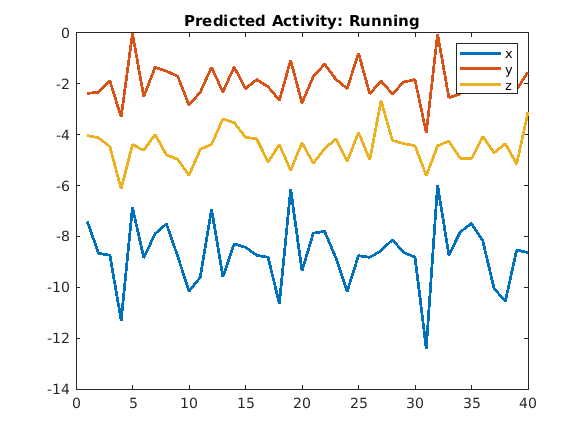

figure
start=40;
step =20;

for i=start:step:length(RawData)/4
     %input= RawData(i-19:i,:);
     FeaturesInput = featuresFromBuffer(RawData(i-start+1:i,:),fs);
     plot(RawData(i-start+1:i,:),'LineWidth',2)
     legend({'x','y','z'})
     predAct = predict(mdl,FeaturesInput);
     title("Predicted Activity: "+Activities(predAct));
     drawnow
end